**EE-414 Speech Processing Lab**

**Lab-5 : PHASE -2**

**21/02/2021**

**AIM**

- To study different sound units present in majority of Indian languages.

- To understand the production mechanism of each sound unit.

- To learn the time domain and frequency domain characteristics of different sound units.

**C. Nasals**

**Theory**

Nasal sounds are similar to vowels having lower formant energy compared to vowels. Nasal sounds are produced with the help of air flow in nasal cavity. The examples of nasal sound units found in Indian languages are /*ng*/, /*nj*/, /*n*/, /*N*/ and /*m*/.

a) Record the sounds of any two nasal sounds.

[y1,Fs] = audioread('ng.wav');
sound(y1,Fs);
[y2,Fs] = audioread('m.wav');
sound(y2,Fs);

b) Plot their time domain waveform, the magnitude spectrum and the spectrogram.

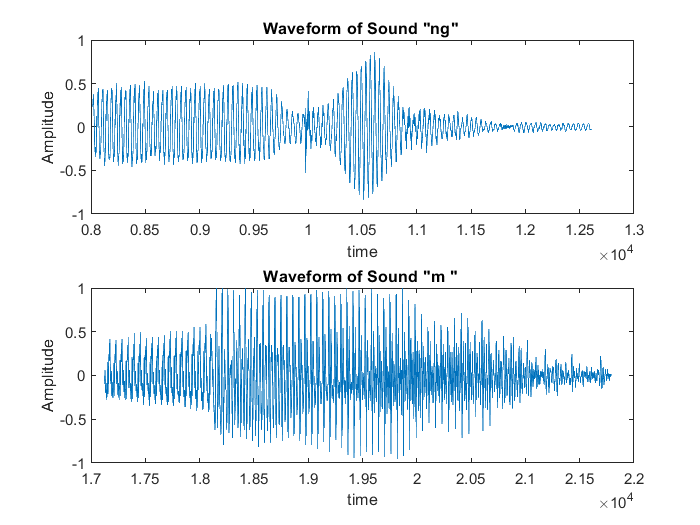

%short_vowel : 'ng'
fs = 16000;
t1=0.501*fs : 0.788*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
s1 = spectrogram(x1); %spectrogram

%long_vowel : 'm'
t2=1.0703*fs : 1.362*fs ; % Time Observed From Wavesurfer
t2=round(t2);
x2=y2(t2);
dF2= fs/length(t2); % Time resolution for "aa" sound
f2=-fs/2:dF2:fs/2-dF2 ; % hz pers sample
X2=fftshift(fft(x2)); % Fourier transform
s2 = spectrogram(x2); %spectrogram

figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "ng" ');
subplot(2,1,2);
plot(t2,x2);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "m " ');

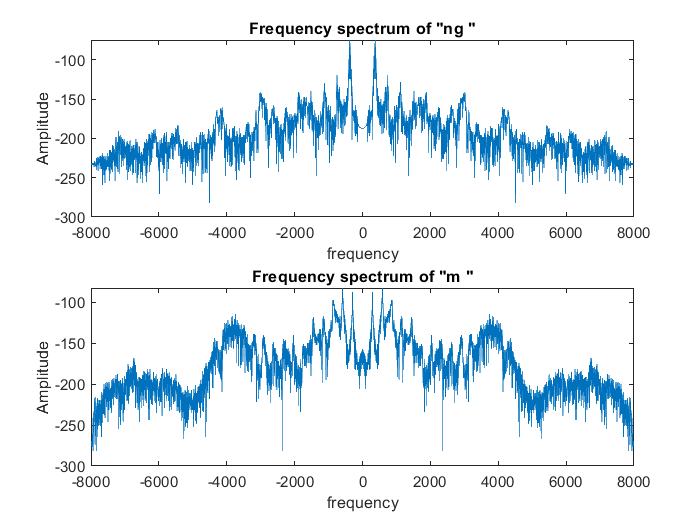


figure();
subplot(2,1,1);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of "ng "');
subplot(2,1,2);
plot(f2,20*log(abs(X2)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of "m "');

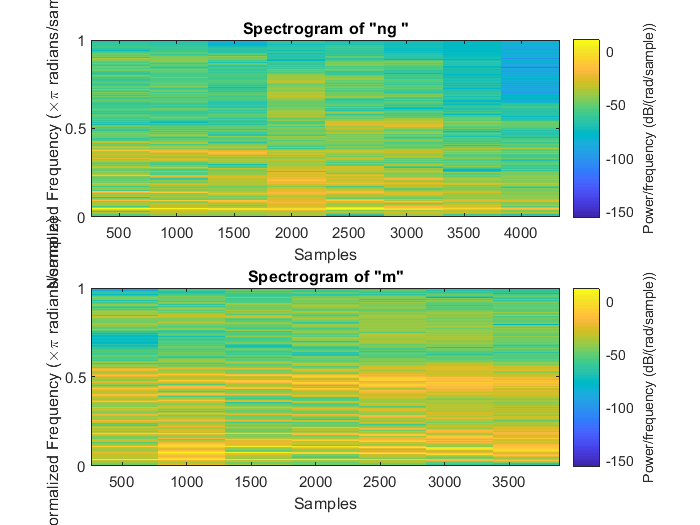


figure();
subplot(2,1,1);
spectrogram(x1,'yaxis')
title('Spectrogram of "ng "');
subplot(2,1,2);
spectrogram(x2,'yaxis')
title('Spectrogram of "m"');

**Comments and observations:**

1) Nasal sounds are similar to vowels having lower energy compared to vowels.

2) The nasal sounds are voiced and having some aspiration noise due to airflow through the nose.

**D) Semi-Vowels**

**Theory **

The set of semivowels in Indian language include /*y*/, /*r*/, /*l*/ and /*v*/.

        Record the sounds of any two semi-vowels and plot their time domain waveform, the magnitude spectrum and the spectrogram.

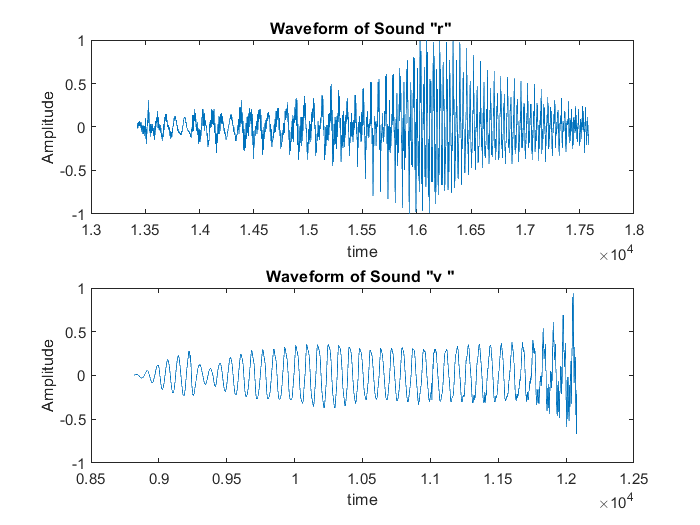

[y1,Fs] = audioread('r.wav');
sound(y1,Fs);
[y2,Fs] = audioread('v.wav');
sound(y2,Fs);

%short_vowel : 'r'
fs = 16000;
t1=0.839*fs : 1.099*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution 
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
s1 = spectrogram(x1); %spectrogram

%long_vowel : 'v'
t2=0.551*fs : 0.755*fs ; % Time Observed From Wavesurfer
t2=round(t2);
x2=y2(t2);
dF2= fs/length(t2); 
f2=-fs/2:dF2:fs/2-dF2 ; % hz pers sample
X2=fftshift(fft(x2)); % Fourier transform
s2 = spectrogram(x2); %spectrogram

figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "r" ');
subplot(2,1,2);
plot(t2,x2);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "v " ');

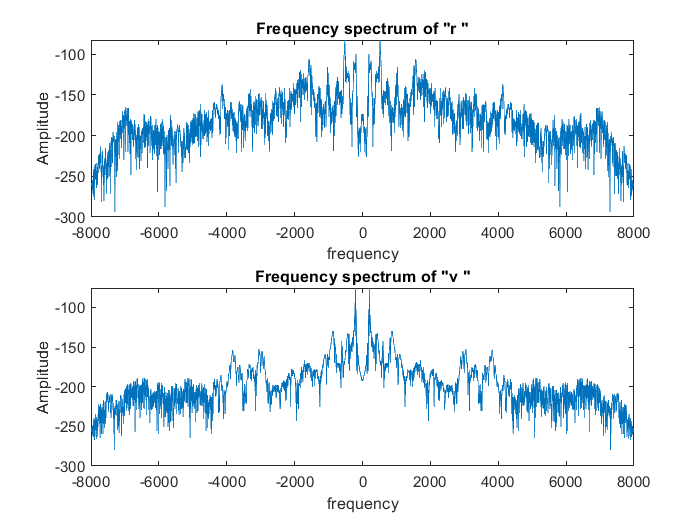


figure();
subplot(2,1,1);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of "r "');
subplot(2,1,2);
plot(f2,20*log(abs(X2)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of "v "');

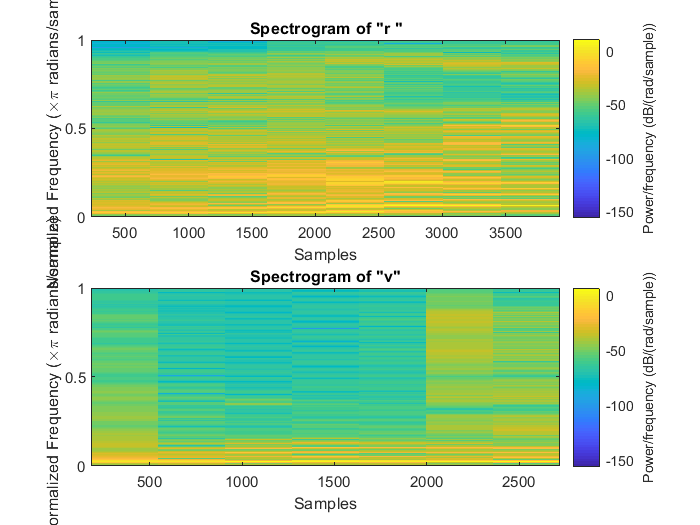


figure();
subplot(2,1,1);
spectrogram(x1,'yaxis')
title('Spectrogram of "r "');
subplot(2,1,2);
spectrogram(x2,'yaxis')
title('Spectrogram of "v"');

**Comments and observations:**

1) Semi vowels are weakly periodic as compared to the vowels 

2) Semi vowels have lower energy as compared to vowels. 

3) From the above plots,  /*r*/ is aspirated and /*v*/ is unaspirated.

**E) Fricatives**

**Theory**

The fricatives are the consonants produced by a narrow constriction somewhere along the length of the vocal tract.  Depending on the place of narrow constrictions, we have different fricatives. In case of most Indian languages we have |s|, |sh|, |shh| & |h| as the fricatives. |s| is a dental fricative, |sh| is an alveolar fricative, |shh| is also an alveolar fricative but with more stress and |h| is a velar fricative.

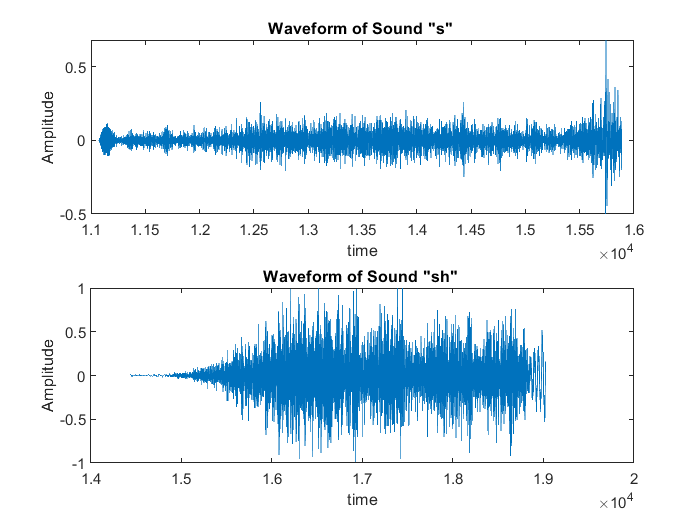

[y1,Fs] = audioread('s.wav');
sound(y1,Fs);
[y2,Fs] = audioread('sh.wav');
sound(y2,Fs);

%short_vowel : 's'
fs = 16000;
t1=0.692*fs : 0.993*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution 
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
s1 = spectrogram(x1); %spectrogram

%long_vowel : 'sh'
t2=0.902*fs : 1.189*fs ; % Time Observed From Wavesurfer
t2=round(t2);
x2=y2(t2);
dF2= fs/length(t2); 
f2=-fs/2:dF2:fs/2-dF2 ; % hz pers sample
X2=fftshift(fft(x2)); % Fourier transform
s2 = spectrogram(x2); %spectrogram

figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "s" ');
subplot(2,1,2);
plot(t2,x2);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "sh" ');

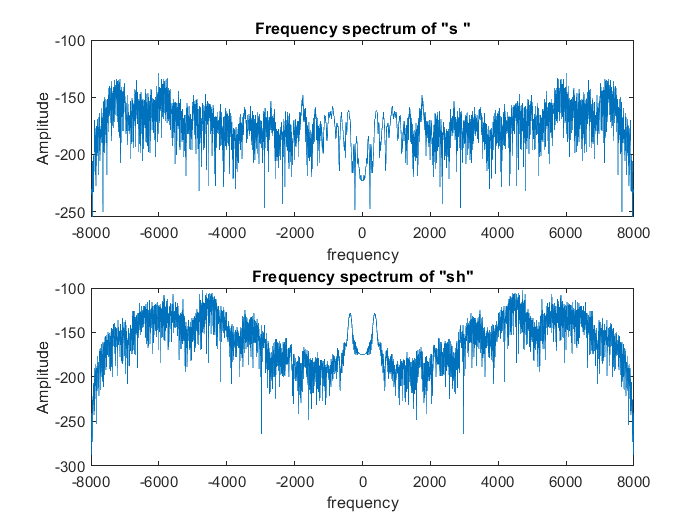


figure();
subplot(2,1,1);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of "s "');
subplot(2,1,2);
plot(f2,20*log(abs(X2)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of "sh"');

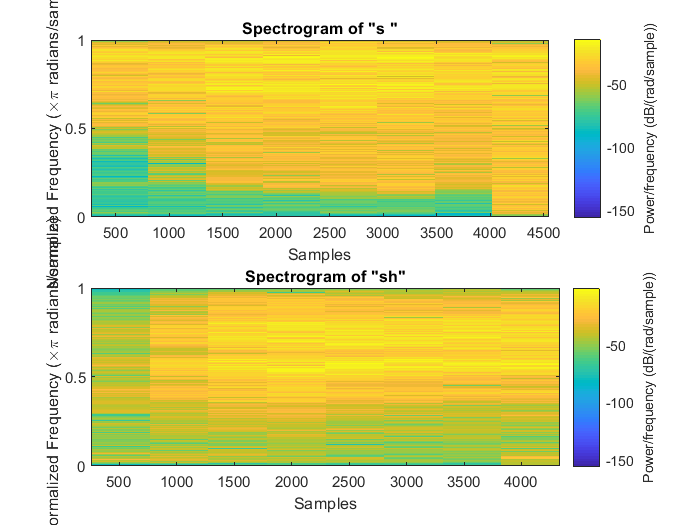


figure();
subplot(2,1,1);
spectrogram(x1,'yaxis')
title('Spectrogram of "s "');
subplot(2,1,2);
spectrogram(x2,'yaxis')
title('Spectrogram of "sh"');

**Comments and observations:**

1) The basic difference between fricatives and stop consonants is that the closure will be partial & narrow in case of fricatives & is complete in case of stop consonants.

2) From the plots it can be observed that, the time domain nature remains same for all the cases, but differ mainly in the amplitude levels and duration. 

3) The concentration of energy is in different regions of the spectrum & hence their is difference in the perceptual quality.

**F) Affricatives**

The affricates are the consonants where the production involves combination of stop and fricative consonant production. Initially, the vocal tract will be completely closed somewhere all the length to create a total constrictions. After this, the constriction will be partially released to create a fricative excitations. Most of the Indian languages have |ch|, |chh|, |j| & |jh| as the affricate consonants. All these affricates are produced at the palatal region. The difference across different affricates is due to different MOA.

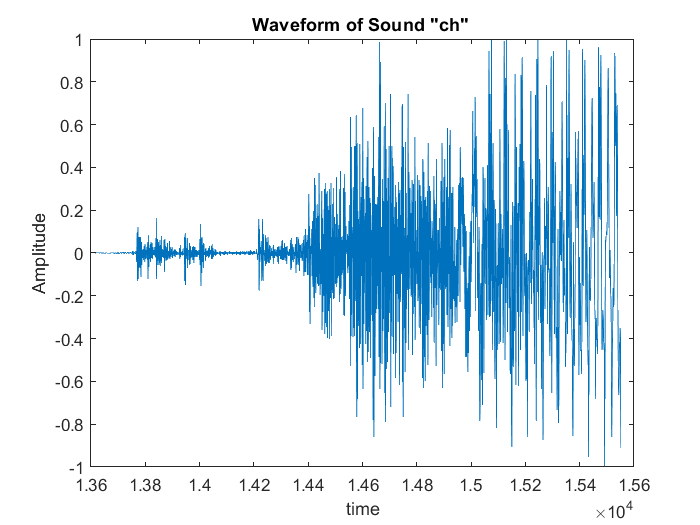

[y1,Fs] = audioread("ch.wav");
sound(y1,Fs);


%short_vowel : 'ch'
fs = 16000;
t1=0.851*fs : 0.972*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution 
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
s1 = spectrogram(x1); %spectrogram


figure();
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "ch" ');

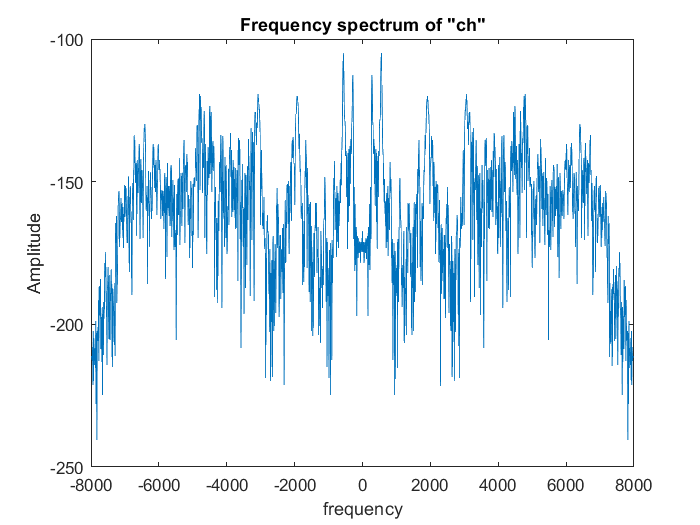


figure();
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of "ch"');

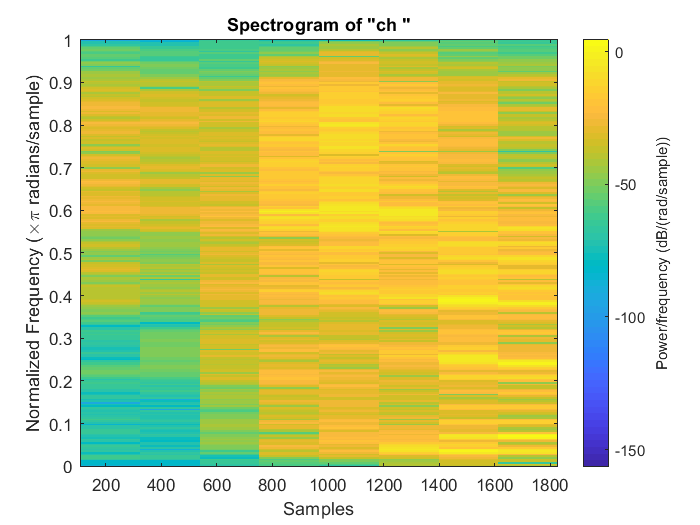


figure();
spectrogram(x1,'yaxis')
title('Spectrogram of "ch "');

**Comments and observations:**

1) Unlike other unvoiced and unaspirated stop consonants /ch/ aperiodic and turbulent in nature.

2) Plosion along with fricative can be observed from the plots.